clear; close all;

global SMOOTH_ON;
SMOOTH_ON = true;

function y = EaseCube(t, start_deg, end_deg)
    len = length(t);
    for i = 1:len
        if t(i) < 0.5
            y(i) = 4*t(i)^3;
        else
            y(i) = 0.5*(2*t(i)-2)^3 + 1;
        end
    end
    y = y.*(end_deg - start_deg) + start_deg;
end

function y = EaseSine(t, start_deg, end_deg)
    len = length(t);
    for i = 1:len
        y(i) = -0.5 * cos(pi*t(i)) + 0.5;
    end
    y = y.*(end_deg - start_deg) + start_deg;
end

function y = smooth(x, K)
    pre = 15;
    post = 15;
    global SMOOTH_ON
    if SMOOTH_ON
        temp = smoothdata([x(end-(pre-1):end), x, x(1:post)], 'sgolay', K);
        y = temp(pre+1:end-post);
    else
        y = x;
    end
end

N = 168;
K=2;    % time_long / time_short ratio
T = 10;

time_long = linspace(0,1, N * K/(K + 1) )

time_long =          0    0.0090    0.0180    0.0270    0.0360    0.0450    0.0541    0.0631    0.0721    0.0811    0.0901    0.0991    0.1081    0.1171    0.1261    0.1351    0.1441    0.1532    0.1622    0.1712    0.1802    0.1892    0.1982    0.2072    0.2162    0.2252    0.2342    0.2432    0.2523    0.2613    0.2703    0.2793    0.2883    0.2973    0.3063    0.3153    0.3243    0.3333    0.3423    0.3514    0.3604    0.3694    0.3784    0.3874    0.3964    0.4054    0.4144    0.4234    0.4324    0.4414


time_short = linspace(0,1,N * 1/(K + 1) )

time_short =          0    0.0182    0.0364    0.0545    0.0727    0.0909    0.1091    0.1273    0.1455    0.1636    0.1818    0.2000    0.2182    0.2364    0.2545    0.2727    0.2909    0.3091    0.3273    0.3455    0.3636    0.3818    0.4000    0.4182    0.4364    0.4545    0.4727    0.4909    0.5091    0.5273    0.5455    0.5636    0.5818    0.6000    0.6182    0.6364    0.6545    0.6727    0.6909    0.7091    0.7273    0.7455    0.7636    0.7818    0.8000    0.8182    0.8364    0.8545    0.8727    0.8909


time_up = linspace(0,1,length(time_short)/2 + T)

time_up =          0    0.0270    0.0541    0.0811    0.1081    0.1351    0.1622    0.1892    0.2162    0.2432    0.2703    0.2973    0.3243    0.3514    0.3784    0.4054    0.4324    0.4595    0.4865    0.5135    0.5405    0.5676    0.5946    0.6216    0.6486    0.6757    0.7027    0.7297    0.7568    0.7838    0.8108    0.8378    0.8649    0.8919    0.9189    0.9459    0.9730    1.0000


time_floor = length(time_long) - 2*T

time_floor = 92


start_deg = [68 112  82 98 90  90  90 90];
end_deg =   [98  82 112 68 75 105 105 75];
shift = [0 N*0.5 N*0.75 N*0.25];


Leg_0 = [EaseSine(time_long, start_deg(1), end_deg(1)) EaseSine(time_short, end_deg(1), start_deg(1))]

Leg_0 =    68.0000   68.0060   68.0240   68.0540   68.0960   68.1499   68.2158   68.2934   68.3829   68.4840   68.5968   68.7211   68.8568   69.0039   69.1622   69.3316   69.5119   69.7030   69.9048   70.1171   70.3396   70.5724   70.8150   71.0675   71.3295   71.6008   71.8813   72.1707   72.4687   72.7752   73.0899   73.4125   73.7428   74.0805   74.4254   74.7771   75.1354   75.5000   75.8706   76.2469   76.6287   77.0155   77.4072   77.8033   78.2035   78.6077   79.0153   79.4261   79.8398   80.2560


Leg_1 = circshift([EaseSine(time_long, start_deg(2), end_deg(2)) EaseSine(time_short, end_deg(2), start_deg(2))], shift(2))

Leg_1 =    86.1707   85.8813   85.6008   85.3295   85.0675   84.8150   84.5724   84.3396   84.1171   83.9048   83.7030   83.5119   83.3316   83.1622   83.0039   82.8568   82.7211   82.5968   82.4840   82.3829   82.2934   82.2158   82.1499   82.0960   82.0540   82.0240   82.0060   82.0000   82.0000   82.0245   82.0978   82.2197   82.3898   82.6076   82.8723   83.1831   83.5390   83.9388   84.3812   84.8647   85.3879   85.9489   86.5459   87.1771   87.8403   88.5334   89.2540   90.0000   90.7688   91.5579


Leg_2 = circshift([EaseSine(time_long, start_deg(3), end_deg(3)) EaseSine(time_short, end_deg(3), start_deg(3))], shift(3))

Leg_2 =    91.4072   91.8033   92.2035   92.6077   93.0153   93.4261   93.8398   94.2560   94.6745   95.0947   95.5165   95.9395   96.3634   96.7877   97.2123   97.6366   98.0605   98.4835   98.9053   99.3255   99.7440  100.1602  100.5739  100.9847  101.3923  101.7965  102.1967  102.5928  102.9845  103.3713  103.7531  104.1294  104.5000  104.8646  105.2229  105.5746  105.9195  106.2572  106.5875  106.9101  107.2248  107.5313  107.8293  108.1187  108.3992  108.6705  108.9325  109.1850  109.4276  109.6604


Leg_3 = circshift([EaseSine(time_long, start_deg(4), end_deg(4)) EaseSine(time_short, end_deg(4), start_deg(4))], shift(4))

Leg_3 =    72.5459   73.1771   73.8403   74.5334   75.2540   76.0000   76.7688   77.5579   78.3647   79.1867   80.0211   80.8653   81.7164   82.5717   83.4283   84.2836   85.1347   85.9789   86.8133   87.6353   88.4421   89.2312   90.0000   90.7460   91.4666   92.1597   92.8229   93.4541   94.0511   94.6121   95.1353   95.6188   96.0612   96.4610   96.8169   97.1277   97.3924   97.6102   97.7803   97.9022   97.9755   98.0000   98.0000   97.9940   97.9760   97.9460   97.9040   97.8501   97.7842   97.7066



Leg_4 = circshift([linspace(start_deg(5), start_deg(5), time_floor) EaseSine(time_up, start_deg(5), end_deg(5)) EaseSine(time_up, end_deg(5), start_deg(5))], T)

Leg_4 =    87.9147   88.3353   88.7138   89.0476   89.3342   89.5716   89.7580   89.8921   89.9730   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000


Leg_5 = circshift([linspace(start_deg(6), start_deg(6), time_floor) EaseSine(time_up, start_deg(6), end_deg(6)) EaseSine(time_up, end_deg(6), start_deg(6))], T+shift(2))

Leg_5 =    90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.0270   90.1079   90.2420   90.4284   90.6658   90.9524   91.2862   91.6647   92.0853   92.5449   93.0403   93.5677   94.1235   94.7036   95.3038   95.9199   96.5474   97.1817   97.8183   98.4526   99.0801   99.6962  100.2964  100.8765  101.4323  101.9597  102.4551  102.9147  103.3353  103.7138  104.0476


Leg_6 = circshift([linspace(start_deg(7), start_deg(7), time_floor) EaseSine(time_up, start_deg(7), end_deg(7)) EaseSine(time_up, end_deg(7), start_deg(7))], T+shift(3))

Leg_6 =     90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90    90


Leg_7 = circshift([linspace(start_deg(8), start_deg(8), time_floor) EaseSine(time_up, start_deg(8), end_deg(8)) EaseSine(time_up, end_deg(8), start_deg(8))], T+shift(4))

Leg_7 =    79.1235   78.5677   78.0403   77.5449   77.0853   76.6647   76.2862   75.9524   75.6658   75.4284   75.2420   75.1079   75.0270   75.0000   75.0000   75.0270   75.1079   75.2420   75.4284   75.6658   75.9524   76.2862   76.6647   77.0853   77.5449   78.0403   78.5677   79.1235   79.7036   80.3038   80.9199   81.5474   82.1817   82.8183   83.4526   84.0801   84.6962   85.2964   85.8765   86.4323   86.9597   87.4551   87.9147   88.3353   88.7138   89.0476   89.3342   89.5716   89.7580   89.8921


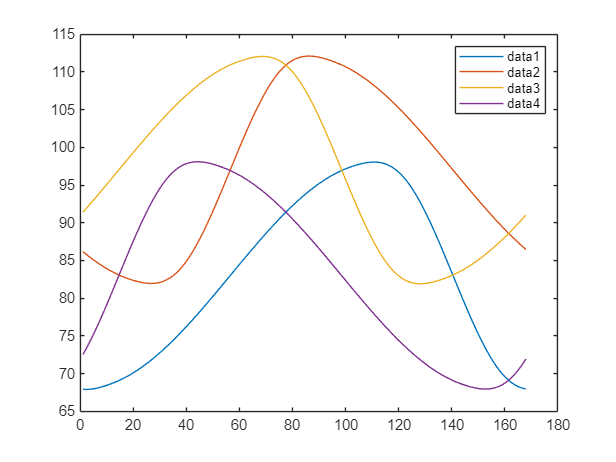


Leg_0 = smooth(Leg_0, 30);
Leg_1 = smooth(Leg_1, 30);
Leg_2 = smooth(Leg_2, 30);
Leg_3 = smooth(Leg_3, 30);

plot(linspace(1,N,N), Leg_0); hold on;
plot(linspace(1,N,N), Leg_1);
plot(linspace(1,N,N), Leg_2);
plot(linspace(1,N,N), Leg_3);
hold off;
legend;

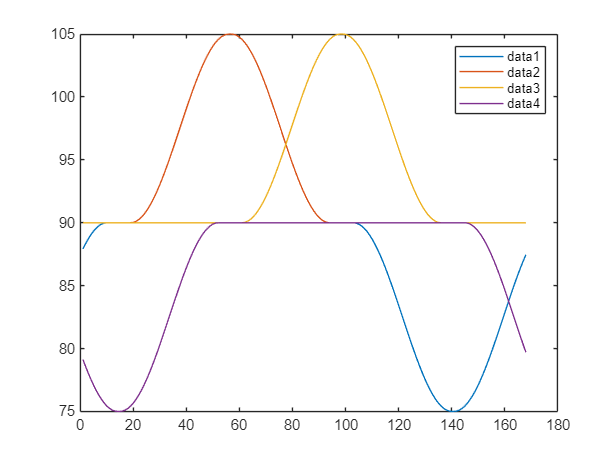


plot([linspace(1,N,N)], Leg_4); hold on;
plot([linspace(1,N,N)], Leg_5);
plot([linspace(1,N,N)], Leg_6);
plot([linspace(1,N,N)], Leg_7);
hold off;
legend;

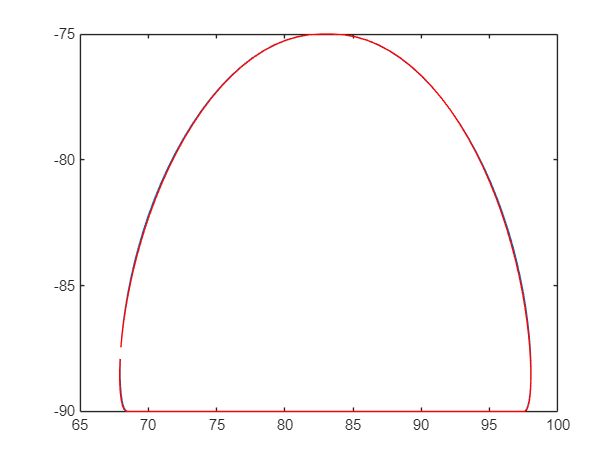


plot(Leg_0, -Leg_4); hold on;
plot(smooth(Leg_0, 30), -Leg_4, 'r'); 
hold off;


% Post-procces commmands
R = 2;
Leg_0 = round(Leg_0, R);
Leg_1 = round(Leg_1, R);
Leg_2 = round(Leg_2, R);
Leg_3 = round(Leg_3, R);
Leg_4 = round(Leg_4, R);
Leg_5 = round(Leg_5, R);
Leg_6 = round(Leg_6, R);
Leg_7 = round(Leg_7, R);


% Create commands
loop_time = 1008;
for i = 1:N
    if i == 1
        fprintf('V1\nE0\nM: %g, %g, %g, %g, %g, %g, %g, %g\nV10\nW100\n----------\n', Leg_0(1), Leg_1(1), Leg_2(1), Leg_3(1), Leg_4(1), Leg_5(1), Leg_6(1), Leg_7(1))
    end
    fprintf('M: %g, %g, %g, %g, %g, %g, %g, %g\n', Leg_0(i), Leg_1(i), Leg_2(i), Leg_3(i), Leg_4(i), Leg_5(i), Leg_6(i), Leg_7(i));
end

V1
E0
M: 67.93, 86.17, 91.4, 72.55, 87.91, 90, 90, 79.12
V10
W100
----------


M: 67.93, 86.17, 91.4, 72.55, 87.91, 90, 90, 79.12
M: 67.91, 85.89, 91.8, 73.17, 88.34, 90, 90, 78.57
M: 67.92, 85.6, 92.2, 73.83, 88.71, 90, 90, 78.04
M: 67.95, 85.33, 92.6, 74.52, 89.05, 90, 90, 77.54
M: 68, 85.07, 93.01, 75.24, 89.33, 90, 90, 77.09
M: 68.06, 84.82, 93.42, 75.99, 89.57, 90, 90, 76.66
M: 68.14, 84.58, 93.84, 76.75, 89.76, 90, 90, 76.29
M: 68.24, 84.34, 94.25, 77.54, 89.89, 90, 90, 75.95
M: 68.34, 84.12, 94.67, 78.35, 89.97, 90, 90, 75.67
M: 68.46, 83.91, 95.09, 79.17, 90, 90, 90, 75.43
M: 68.58, 83.71, 95.51, 80, 90, 90, 90, 75.24
M: 68.71, 83.52, 95.94, 80.84, 90, 90, 90, 75.11
M: 68.86, 83.33, 96.36, 81.69, 90, 90, 90, 75.03
M: 69, 83.17, 96.78, 82.54, 90, 90, 90, 75
M: 69.16, 83.01, 97.21, 83.4, 90, 90, 90, 75
M: 69.33, 82.86, 97.63, 84.25, 90, 90, 90, 75.03
M: 69.51, 82.72, 98.06, 85.1, 90, 90, 90, 75.11
M: 69.7, 82.59, 98.48, 85.94, 90, 90, 90, 75.24
M: 69.9, 82.47, 98.9, 86.78, 90, 90, 90, 75.43
M: 70.12, 82.36, 99.32, 87.6, 90, 90.03, 90, 75.67
M: 70.34, 82.26,